% Variables
zeta = 0.04869;
omega_n  = 8.38187;
WL = 0.04;
WR = 0.02;
a = 0.120*0.64;
b = 0.069168;
c = 0.023251;
Tot_M = WL*b-WR*c;
J = Tot_M/omega_n^2;        % Momento de inercia (kg·m^2)
B = J*2*zeta*omega_n*5.5;       % Fricción Viscosa (kg·m^2/s)
BJ = B/J;
TotJ = Tot_M/J;
aJ = a/J;
MotC = 0.0247;              % Constante motor (N/V)
deadZ = 0.09;


A_Dir = [0      1;
    -omega_n^2  -2*zeta*omega_n];
B_Dir = [0; a * MotC / J];
C_Dir = [1 0];
D_Dir = 0;

sistema = ss(A_Dir , B_Dir, C_Dir, D_Dir);  % Modelo de segundo orden

% Parámetros Filtros H infinito  
M = [1.1, 0.05];
A = [0.0002,1.05];
wB = [6.5*2*pi,100*2*pi];

% Generación Filtros H infinito
W1pos = makeweight(25,[100 0.0251],0.000175);
W2 = tf(0.01 , 1);
W3 = makeweight(0.01,[40 2], 8);

W1_long_vel = 1;
W = []


W =

     []



W1 = W1pos


W1 =
 
  A = 
            x1
   x1  -0.1004
 
  B = 
       u1
   x1   2
 
  C = 
          x1
   y1  1.255
 
  D = 
             u1
   y1  0.000175
 
Continuous-time state-space model.


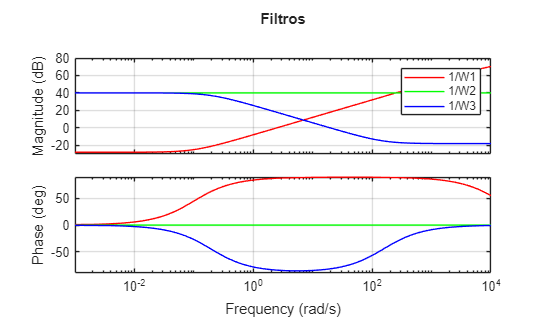


% Definimos los parámetro



figure

bode(1/W1, 'r');
hold on
bode(1/W2(1,1), 'g')
bode(1/W3, 'b')
title('Filtros')
legend('1/W1','1/W2','1/W3')
grid on
hold off

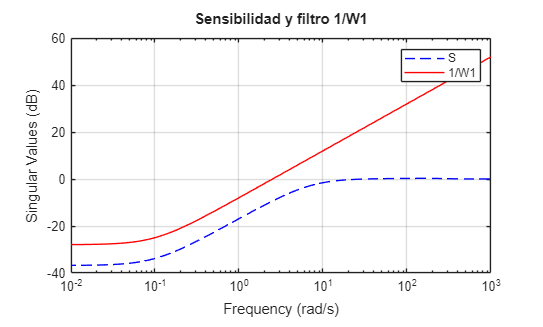

P = augw(sistema,W1,W2,W3);

%Síntesis del Controlador 
 y_meas = 1;
u_cont = 1;
[K, sysCL, gam, info] = hinfsyn(P, y_meas, u_cont);

%Comprobación 

L = sistema*K;
S = feedback(eye(1),L);

figure
%sigma(S(1,:),'r--');
hold on
sigma(S,'b--');
sigma(1/W1,'r');
title('Sensibilidad y filtro 1/W1')
legend('S','1/W1')
grid on
hold off

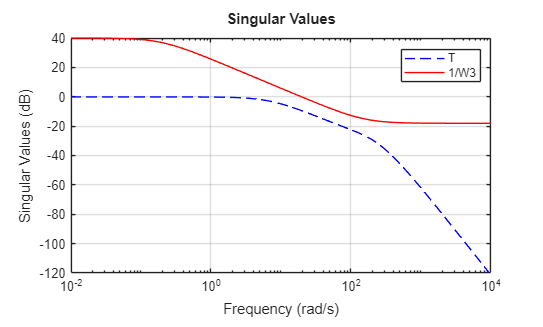

% Esfuerzo de control

figure
hold on
T = S*L;
sigma(T, 'b--')
sigma(1/W3,'r');
legend('T','1/W3')
grid on;
hold off

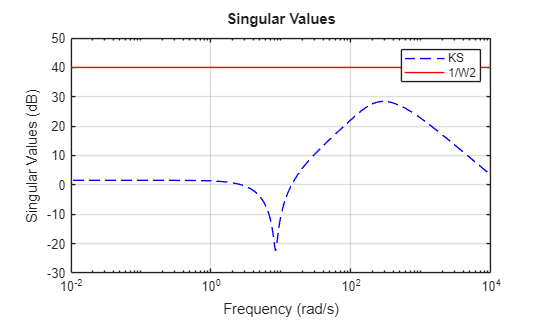

% Rehazo al ruido

figure
hold on
KS = K*S;
sigma(KS, 'b--')
sigma(1/W2,'r');
legend('KS','1/W2')
grid on;
hold off

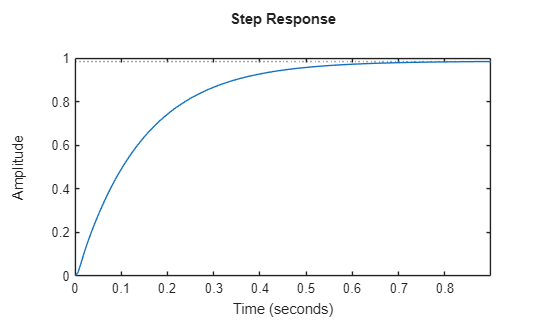

prueba = feedback(K*sistema, eye(size(K*sistema,2)));
step(prueba)